# **Exercise 9a**

**Objective**: 

The purpose of this lab is to create a MATLAB function to generate smooth paths between given start and end points, specified by their initial and final coordinates and angles. This task demonstrates the use of symbolic algebra and polynomial interpolation to construct a continuous path with controlled orientation.

## **Introduction:**

In path generation and control applications, it is often necessary to define a smooth trajectory between two points. This lab uses a cubic polynomial to generate a smooth path from an initial position and orientation to a final position and orientation. By using MATLAB's symbolic capabilities, we calculate the coefficients of the polynomial to ensure smooth transitions in both the X and Y coordinates. The generated paths are then visualized in a plot for analysis.

## **Path Visualization**:

- The computed paths are visualized using MATLAB's plotting functions.

- Three example paths are generated with specific start and end points and angles.

- Each path is plotted in a subplot to allow side-by-side comparison of the results.

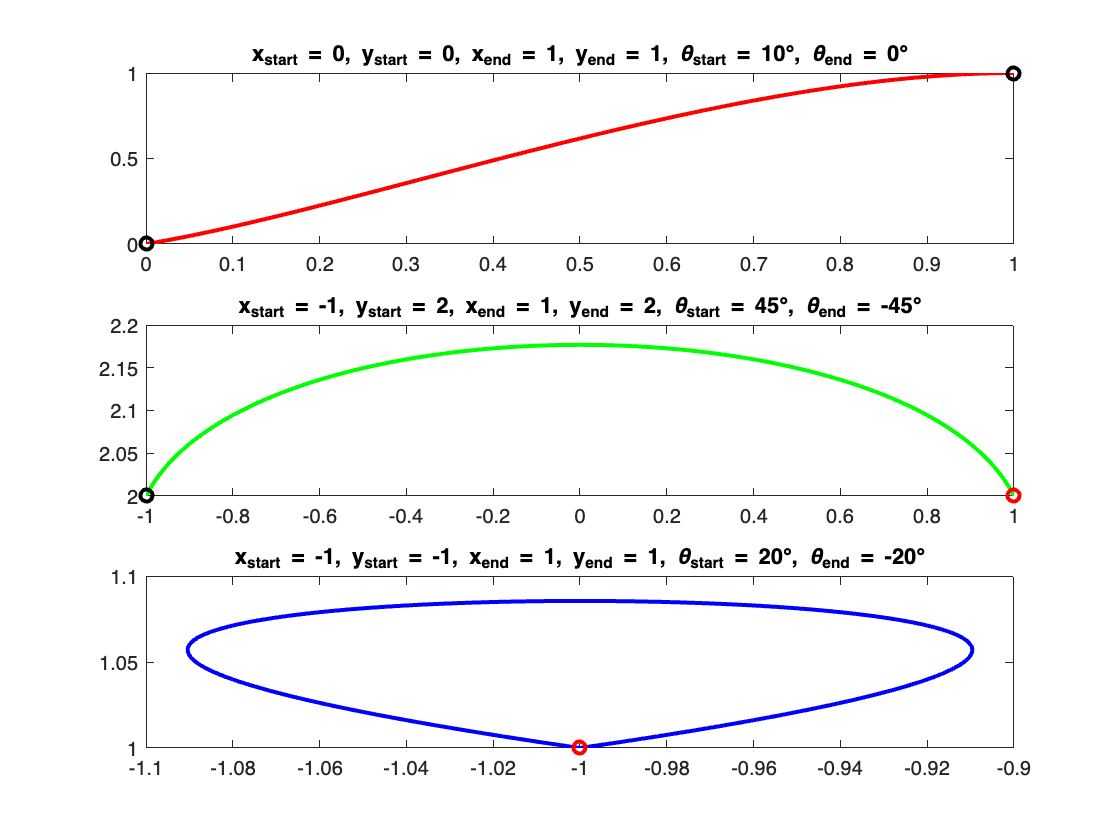

% Generate paths using initial and final points with angles
[x_path1, y_path1] = compute_path(0, 1, 0, 1, 40, 0); % Path 1: Start at (0,0), end at (1,1), initial angle 10°, final angle 0°
[x_path2, y_path2] = compute_path(-1, 1, 2, 2, 45, -45); % Path 2: Start at (-1,2), end at (1,2), initial angle 45°, final angle -45°
[x_path3, y_path3] = compute_path(-1, -1, 1, 1, 20, -20); % Path 3: Start at (-1,-1), end at (1,1), initial angle 20°, final angle -20°

% Plot path 1
subplot(3, 1, 1); % Divide the figure into 3 rows and select the 1st plot
plot(x_path1, y_path1, 'r-', 0, 0, 'ko', 1, 1, 'ko', 'LineWidth', 2); % Plot path 1 with green lines
title('x_{start} = 0, y_{start} = 0, x_{end} = 1, y_{end} = 1, \theta_{start} = 10°, \theta_{end} = 0°'); % Title with parameters

% Plot path 2
subplot(3, 1, 2); % Select the 2nd plot in the 3-row figure
plot(x_path2, y_path2, 'g-', -1, 2, 'ko', 1, 2, 'ro', 'LineWidth', 2); % Plot path 2 with red circles
title('x_{start} = -1, y_{start} = 2, x_{end} = 1, y_{end} = 2, \theta_{start} = 45°, \theta_{end} = -45°'); % Title with parameters

% Plot path 3
subplot(3, 1, 3); % Select the 3rd plot in the 3-row figure
plot(x_path3, y_path3, 'b-', -1, 1, 'ro', 'LineWidth', 2); % Plot path 3 with red circles
title('x_{start} = -1, y_{start} = -1, x_{end} = 1, y_{end} = 1, \theta_{start} = 20°, \theta_{end} = -20°'); % Title with parameters



% function compute path at the end

**Results**

The plots display three paths between specified start and end points with the defined initial and final angles. Each path is a smooth curve that satisfies the input boundary conditions:

- **Path 1**: Moves from (0,0) to (1,1) with a change in angle from 40° to 0°.

- **Path 2**: Moves from (-1,2) to (1,2) with a change in angle from 45° to -45°.

- **Path 3**: Moves from (-1,-1) to (1,1) with a change in angle from 20° to -20°.

**Discussion**

The results demonstrate the ability of cubic polynomials to create smooth paths while maintaining specified positions and orientations. The use of symbolic variables and linear systems for solving polynomial coefficients provides **flexibility for generating various paths** based on initial and final constraints.

# **Exercise 9b**

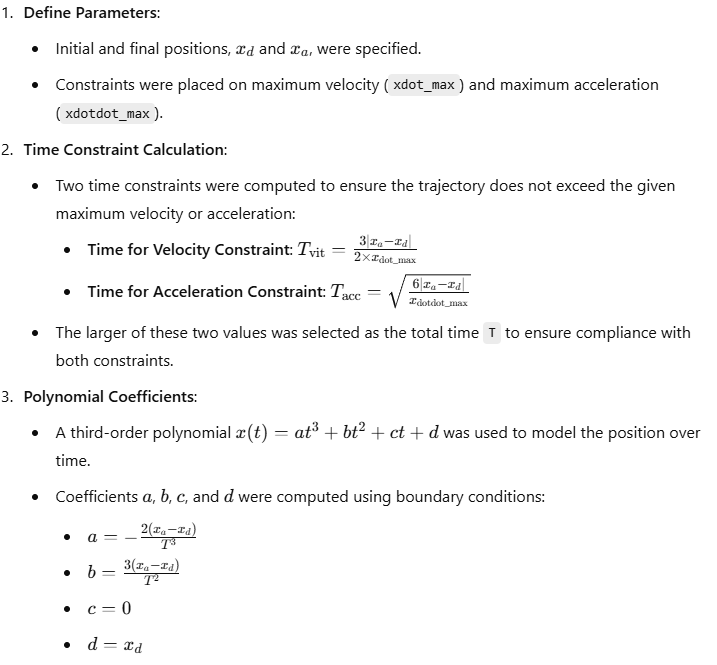

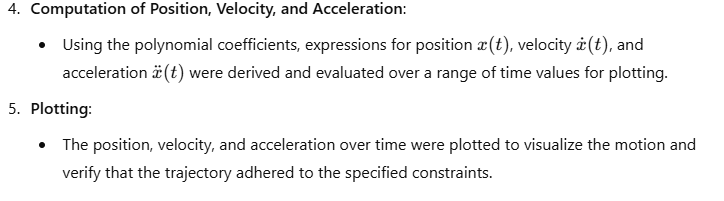

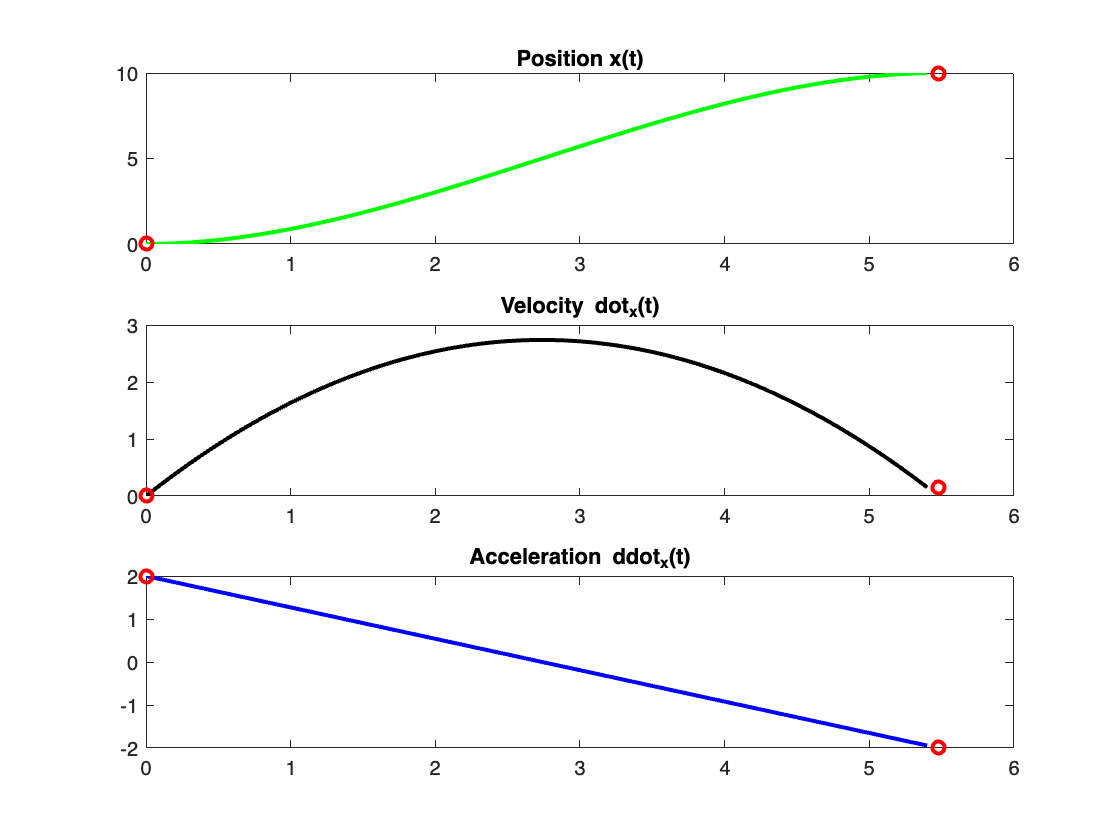



% Parameters
%warning('off', '');
xa = 10; % Final position
xd = 0; % Initial position
xdot_max = 5; % Maximum velocity constraint
xdotdot_max = 2; % Maximum acceleration constraint

% Calculate Time Constraints for Velocity and Acceleration
T_vit = 3 * abs(xa - xd) / (2 * xdot_max);
T_acc = sqrt(6 * abs(xa - xd) / xdotdot_max);

% Choose the larger of the two time constraints to satisfy both
T = max(T_vit, T_acc);

% Polynomial coefficients for the third-order polynomial x(t) = at^3 + bt^2 + ct + d
a = -2 * (xa - xd) / T^3;
b = 3 * (xa - xd) / T^2;
c = 0;
d = xd;

% Define time vector for plotting
t = 0:0.1:T;

% Compute the position, velocity, and acceleration over time
x_t = a * t.^3 + b * t.^2 + c * t + d;
x_dot_t = 3 * a * t.^2 + 2 * b * t + c;
x_dotdot_t = 6 * a * t + 2 * b;

% Plot the results
figure;
subplot(3,1,1);
plot(t, x_t, 'g-', 0, 0, 'ro', T, 10, 'ro', 'LineWidth', 2);
title('Position x(t)');

subplot(3,1,2);
plot(t, x_dot_t, 'k-', 0, 0, 'ro', T, 0.15, 'ro', 'LineWidth', 2);
title('Velocity dot_x(t)');


subplot(3,1,3);
plot(t, x_dotdot_t, 'b-', 0, 2, 'ro', T,-2, 'ro', 'LineWidth', 2);
title('Acceleration ddot_x(t)');

# **Function**

## **Path Generation Function (**`compute_path`**)**:

- The MATLAB function `compute_path` is defined to take in starting and ending coordinates (`x_start`, `y_start`, `x_end`, `y_end`) and angles (`angle_start`, `angle_end`) at the start and end points.

- The function uses symbolic variables for the coefficients of a cubic polynomial in both the X and Y directions.

- Four equations are set up for each axis, based on the boundary conditions for position and orientation.

- MATLAB's `linsolve` function is used to solve these equations and obtain the coefficients of the polynomial.

function [x_path, y_path] = compute_path(x_start, x_end, y_start, y_end, angle_start, angle_end)
    syms b_0x b_1x b_2x b_3x b_0y b_1y b_2y b_3y;

    t = 0:0.01:1;

    % X-axis equations
    eq_x1 = b_0x == x_start;
    eq_x2 = b_3x + b_2x + b_1x + b_0x == x_end;
    eq_x3 = b_1x == cosd(angle_start);
    eq_x4 = 3*b_3x + 2*b_2x + b_1x == cosd(angle_end);

    % Y-axis equations
    eq_y1 = b_0y == y_start;
    eq_y2 = b_3y + b_2y + b_1y + b_0y == y_end;
    eq_y3 = b_1y == sind(angle_start);
    eq_y4 = 3*b_3y + 2*b_2y + b_1y == sind(angle_end);

    % Variables for solving equations
    x_coeffs = [b_3x, b_2x, b_1x, b_0x];
    y_coeffs = [b_3y, b_2y, b_1y, b_0y];

    % Constructing matrices for X and Y equations
    X_equations = [eq_x1, eq_x2, eq_x3, eq_x4];
    Y_equations = [eq_y1, eq_y2, eq_y3, eq_y4];
    [A_x, B_x] = equationsToMatrix(X_equations, x_coeffs);
    [A_y, B_y] = equationsToMatrix(Y_equations, y_coeffs);

    % Solving the parameter matrices
    X_solution = linsolve(A_x, B_x);
    Y_solution = linsolve(A_y, B_y);

    % Calculating the paths
    x_path = X_solution(1).*t.^3 + X_solution(2).*t.^2 + X_solution(3).*t + X_solution(4);
    y_path = Y_solution(1).*t.^3 + Y_solution(2).*t.^2 + Y_solution(3).*t + Y_solution(4);
end
